# Two-lung model

clear all

syms i_L1(t) i_L2(t)
syms i_U1(t) i_U2(t)
syms i_E1(t) i_E2(t)
syms i_M(t) i_O(t)
syms v_L1(t) v_L2(t)
syms q_L1(t) q_L2(t)

syms v_M
syms C_L1 C_L2
syms R_M R_O
syms R_U1 R_D1 R_L1 R_U2 R_D2 R_L2 R_E1 R_E2

eqn1 = i_L1(t) == C_L1 * diff(v_L1(t));
eqn2 = i_L2(t) == C_L2 * diff(v_L2(t));

eqn3 = i_U1(t) == i_L1(t) + i_E1(t);
eqn4 = i_U2(t) == i_L2(t) + i_E2(t);
eqn5 = i_M(t) == i_U1(t) + i_U2(t);

eqn6 = diff(q_L1(t)) == i_L1(t);
eqn7 = diff(q_L2(t)) == i_L2(t);

eqn8 = v_M - i_M(t)*R_M - i_U1(t)*R_U1 - i_L1(t)*R_D1 - i_L1(t)*R_L1 == v_L1(t);
eqn9 = v_M - i_M(t)*R_M - i_U2(t)*R_U2 - i_L2(t)*R_D2 - i_L2(t)*R_L2 == v_L2(t);

% Exhale only
eqn10e = v_M - i_M(t)*R_M - i_U1(t)*R_U1 - i_E1(t)*R_E1 - i_O(t)*R_O  == 0;
eqn11e = v_M - i_M(t)*R_M - i_U2(t)*R_U2 - i_E2(t)*R_E2 - i_O(t)*R_O  == 0;
eqn12e = i_O(t) == i_E1(t) + i_E2(t);

% Inhale only
eqn10i = i_O(t) == 0;
eqn11i = i_E1(t) == 0;
eqn12i = i_E2(t) == 0;

eqns = [eqn1 eqn2 eqn3 eqn4 eqn5 eqn6 eqn7 eqn8 eqn9]

$$eqns = \left(\begin{array}{ccccccccc} i_{\mathrm{L1}}\left(t\right)=C_{\mathrm{L1}}\,\frac{\partial }{\partial t}v_{\mathrm{L1}}\left(t\right) & i_{\mathrm{L2}}\left(t\right)=C_{\mathrm{L2}}\,\frac{\partial }{\partial t}v_{\mathrm{L2}}\left(t\right) & i_{\mathrm{U1}}\left(t\right)=i_{\mathrm{E1}}\left(t\right)+i_{\mathrm{L1}}\left(t\right) & i_{\mathrm{U2}}\left(t\right)=i_{\mathrm{E2}}\left(t\right)+i_{\mathrm{L2}}\left(t\right) & i_{M}\left(t\right)=i_{\mathrm{U1}}\left(t\right)+i_{\mathrm{U2}}\left(t\right) & \frac{\partial }{\partial t}q_{\mathrm{L1}}\left(t\right)=i_{\mathrm{L1}}\left(t\right) & \frac{\partial }{\partial t}q_{\mathrm{L2}}\left(t\right)=i_{\mathrm{L2}}\left(t\right) & v_{M}-R_{\mathrm{D1}}\,i_{\mathrm{L1}}\left(t\right)-R_{\mathrm{L1}}\,i_{\mathrm{L1}}\left(t\right)-R_{M}\,i_{M}\left(t\right)-R_{\mathrm{U1}}\,i_{\mathrm{U1}}\left(t\right)=v_{\mathrm{L1}}\left(t\right) & v_{M}-R_{\mathrm{D2}}\,i_{\mathrm{L2}}\left(t\right)-R_{\mathrm{L2}}\,i_{\mathrm{L2}}\left(t\right)-R_{M}\,i_{M}\left(t\right)-R_{\mathrm{U2}}\,i_{\mathrm{U2}}\left(t\right)=v_{\mathrm{L2}}\left(t\right) \end{array}\right)$$

inhale = [eqns eqn10i eqn11i eqn12i]

$$inhale = \left(\begin{array}{cccccccccccc} i_{\mathrm{L1}}\left(t\right)=C_{\mathrm{L1}}\,\frac{\partial }{\partial t}v_{\mathrm{L1}}\left(t\right) & i_{\mathrm{L2}}\left(t\right)=C_{\mathrm{L2}}\,\frac{\partial }{\partial t}v_{\mathrm{L2}}\left(t\right) & i_{\mathrm{U1}}\left(t\right)=i_{\mathrm{E1}}\left(t\right)+i_{\mathrm{L1}}\left(t\right) & i_{\mathrm{U2}}\left(t\right)=i_{\mathrm{E2}}\left(t\right)+i_{\mathrm{L2}}\left(t\right) & i_{M}\left(t\right)=i_{\mathrm{U1}}\left(t\right)+i_{\mathrm{U2}}\left(t\right) & \frac{\partial }{\partial t}q_{\mathrm{L1}}\left(t\right)=i_{\mathrm{L1}}\left(t\right) & \frac{\partial }{\partial t}q_{\mathrm{L2}}\left(t\right)=i_{\mathrm{L2}}\left(t\right) & v_{M}-R_{\mathrm{D1}}\,i_{\mathrm{L1}}\left(t\right)-R_{\mathrm{L1}}\,i_{\mathrm{L1}}\left(t\right)-R_{M}\,i_{M}\left(t\right)-R_{\mathrm{U1}}\,i_{\mathrm{U1}}\left(t\right)=v_{\mathrm{L1}}\left(t\right) & v_{M}-R_{\mathrm{D2}}\,i_{\mathrm{L2}}\left(t\right)-R_{\mathrm{L2}}\,i_{\mathrm{L2}}\left(t\right)-R_{M}\,i_{M}\left(t\right)-R_{\mathrm{U2}}\,i_{\mathrm{U2}}\left(t\right)=v_{\mathrm{L2}}\left(t\right) & i_{O}\left(t\right)=0 & i_{\mathrm{E1}}\left(t\right)=0 & i_{\mathrm{E2}}\left(t\right)=0 \end{array}\right)$$

exhale = [eqns eqn10e eqn11e eqn12e]

$$exhale = \left(\begin{array}{cccccccccccc} i_{\mathrm{L1}}\left(t\right)=C_{\mathrm{L1}}\,\frac{\partial }{\partial t}v_{\mathrm{L1}}\left(t\right) & i_{\mathrm{L2}}\left(t\right)=C_{\mathrm{L2}}\,\frac{\partial }{\partial t}v_{\mathrm{L2}}\left(t\right) & i_{\mathrm{U1}}\left(t\right)=i_{\mathrm{E1}}\left(t\right)+i_{\mathrm{L1}}\left(t\right) & i_{\mathrm{U2}}\left(t\right)=i_{\mathrm{E2}}\left(t\right)+i_{\mathrm{L2}}\left(t\right) & i_{M}\left(t\right)=i_{\mathrm{U1}}\left(t\right)+i_{\mathrm{U2}}\left(t\right) & \frac{\partial }{\partial t}q_{\mathrm{L1}}\left(t\right)=i_{\mathrm{L1}}\left(t\right) & \frac{\partial }{\partial t}q_{\mathrm{L2}}\left(t\right)=i_{\mathrm{L2}}\left(t\right) & v_{M}-R_{\mathrm{D1}}\,i_{\mathrm{L1}}\left(t\right)-R_{\mathrm{L1}}\,i_{\mathrm{L1}}\left(t\right)-R_{M}\,i_{M}\left(t\right)-R_{\mathrm{U1}}\,i_{\mathrm{U1}}\left(t\right)=v_{\mathrm{L1}}\left(t\right) & v_{M}-R_{\mathrm{D2}}\,i_{\mathrm{L2}}\left(t\right)-R_{\mathrm{L2}}\,i_{\mathrm{L2}}\left(t\right)-R_{M}\,i_{M}\left(t\right)-R_{\mathrm{U2}}\,i_{\mathrm{U2}}\left(t\right)=v_{\mathrm{L2}}\left(t\right) & v_{M}-R_{\mathrm{E1}}\,i_{\mathrm{E1}}\left(t\right)-R_{M}\,i_{M}\left(t\right)-R_{O}\,i_{O}\left(t\right)-R_{\mathrm{U1}}\,i_{\mathrm{U1}}\left(t\right)=0 & v_{M}-R_{\mathrm{E2}}\,i_{\mathrm{E2}}\left(t\right)-R_{M}\,i_{M}\left(t\right)-R_{O}\,i_{O}\left(t\right)-R_{\mathrm{U2}}\,i_{\mathrm{U2}}\left(t\right)=0 & i_{O}\left(t\right)=i_{\mathrm{E1}}\left(t\right)+i_{\mathrm{E2}}\left(t\right) \end{array}\right)$$


vars = [v_L1(t); v_L2(t); q_L1(t); q_L2(t); i_L1(t); i_L2(t); i_U1(t); i_U2(t); i_M(t); i_E1(t); i_E2(t); i_O(t)]

$$vars = \left(\begin{array}{c} v_{\mathrm{L1}}\left(t\right)\\ v_{\mathrm{L2}}\left(t\right)\\ q_{\mathrm{L1}}\left(t\right)\\ q_{\mathrm{L2}}\left(t\right)\\ i_{\mathrm{L1}}\left(t\right)\\ i_{\mathrm{L2}}\left(t\right)\\ i_{\mathrm{U1}}\left(t\right)\\ i_{\mathrm{U2}}\left(t\right)\\ i_{M}\left(t\right)\\ i_{\mathrm{E1}}\left(t\right)\\ i_{\mathrm{E2}}\left(t\right)\\ i_{O}\left(t\right) \end{array}\right)$$

%vars_exhale = [vars_inhale; ]
origVars = length(vars);


## Check and Reduce Differential Index

Mexhale = incidenceMatrix(exhale,vars);
isLowIndexDAE(exhale,vars)

ans = logical
   1


[DAEexhale,DAEvars_exhale] = reduceDAEIndex(exhale,vars);
%[DAEexhale,DAEvars_exhale] = reduceRedundancies(DAEexhale,DAEvars_exhale);

Minhale = incidenceMatrix(inhale,vars);
isLowIndexDAE(inhale,vars)

ans = logical
   1


[DAEinhale,DAEvars_inhale] = reduceDAEIndex(inhale,vars);
%[DAEinhale,DAEvars_inhale] = reduceRedundancies(DAEinhale,DAEvars_inhale);


## Convert DAE System to MATLAB Function Handles

pDAEs_exhale = symvar(DAEexhale);
pDAEvars_exhale = symvar(DAEvars_exhale);
%extraParams_exhale = setdiff(pDAEs_exhale,pDAEvars_exhale);

f_exhale = daeFunction(DAEexhale,DAEvars_exhale,v_M,R_M,R_U1,R_U2,R_D1,R_D2,R_L1,R_L2,C_L1,C_L2,R_E1,R_E2,R_O);
f_inhale = daeFunction(DAEinhale,DAEvars_inhale,v_M,R_M,R_U1,R_U2,R_D1,R_D2,R_L1,R_L2,C_L1,C_L2,R_E1,R_E2,R_O);


## Set the parameter values and create the function handle for ode15i.

v_M_exhale = 5% Pa PEEP = 5cmH20

v_M_exhale = 5

v_M_inhale = 20 % PIP = 20cmH2O

v_M_inhale = 20

R_M = 1 % Pa*s/m^3

R_M = 1

% current = m^3/s
% charge = m^3
% tube length = 1.5 m?
R_U1 = 1

R_U1 = 1

R_U2 = 1

R_U2 = 1

R_D1 = 1

R_D1 = 1

R_D2 = 1

R_D2 = 1


R_L1 = 1e2 % want 2.0cmH2O/L/s

R_L1 = 100

R_L2 = 1e2

R_L2 = 200

C_L1 = 1e-3 % 0.064 L/cmH2O into m^3/Pa

C_L1 = 1.0000e-03

C_L2 = 2e-3

C_L2 = 0.0020


R_E1 = 1

R_E1 = 1

R_E2 = 1

R_E2 = 1

R_O = 1

R_O = 1


F_exhale = @(t,Y,YP) f_exhale(t,Y,YP,v_M_exhale,R_M,R_U1,R_U2,R_D1,R_D2,R_L1,R_L2,C_L1,C_L2,R_E1,R_E2,R_O);
F_inhale = @(t,Y,YP) f_inhale(t,Y,YP,v_M_inhale,R_M,R_U1,R_U2,R_D1,R_D2,R_L1,R_L2,C_L1,C_L2,R_E1,R_E2,R_O);


## Find consistent initial values for the variables and their derivatives

%opt = odeset('RelTol', 10.0^(-7),'AbsTol',10.0^(-7));

%vars
y0est = [v_M_inhale; v_M_inhale; 0;0; zeros(length(vars)-4,1)];
yp0est = zeros(length(vars),1);
[y0,yp0] = decic(F_exhale,0,y0est,[],yp0est,[])

y0 =    20.0000
   20.0000
         0
         0
   -0.1711
   -0.0862
    0.7478
    0.7902
    1.5380
    0.9189


yp0 =  -171.1460
  -43.1050
   -0.1711
   -0.0862
         0
         0
         0
         0
         0
         0


## Solve DAEs Using ode15i

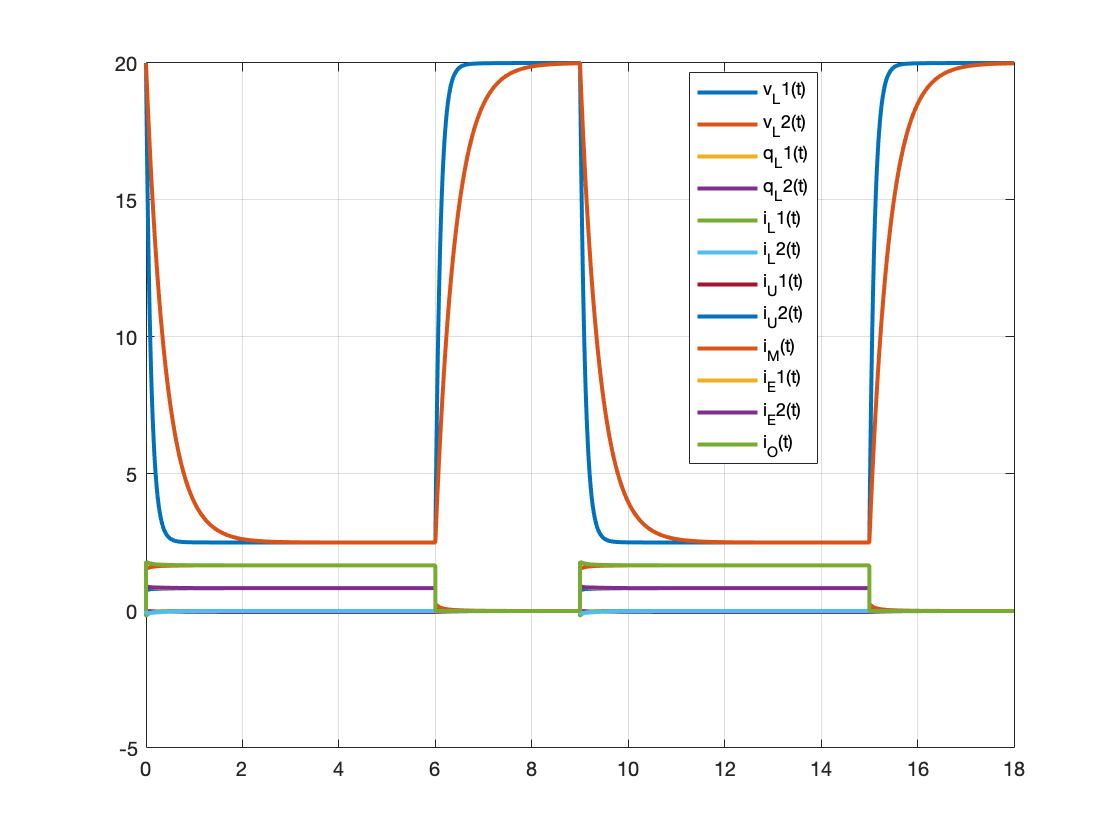

tExhale = 6;
tInhale = 3;


tSol = [];
ySol = [];
ti = 0;
for i = 1:3 % repeat for a number of cycles
    
    %exhale
    [tSole,ySole] = ode15i(F_exhale,[ti ti+tExhale],y0,yp0);
    tSol = [tSol; tSole];
    ySol = [ySol; ySole];
    [y0,yp0] = decic(F_inhale,1,ySole(end,1:origVars),[1 1 zeros(1,length(vars)-2)],yp0est,[]); % initial conditions for next phase
    ti = ti+tExhale;
    
    %inhale
    
    [tSoli,ySoli] = ode15i(F_inhale,[ti ti+tInhale],y0,yp0);
    tSol = [tSol; tSoli];
    ySol = [ySol; ySoli];
    [y0,yp0] = decic(F_inhale,1,ySoli(end,1:origVars),[1 1 zeros(1,length(vars)-2)],yp0est,[]); % initial conditions for next phase
    
    ti = ti+tInhale;
    
end

%% Plot
plot(tSol,ySol(:,1:origVars),'LineWidth',2)

for k = 1:origVars
    S{k} = char(DAEvars_inhale(k));
end
legend(S,'Location','Best')
grid on